close("all"); clear; clc;
setmadsympath();

speed = 130;
root = "G:\My Drive\BikeSimResults\BigSports\Chicane\";
dir = root + "Vx" + speed + "Kph\";
ref = readtable(dir + "bikesim_results_"+ speed + "kph");

params = bigSportsParameters();
p = bikeSimToPrydeParameters(params,speed/3.6);

yaw_rate = deg2rad(ref.AV_Y);
camber = deg2rad(ref.Roll);
vx = ref.Vxo/3.6;

steer = deg2rad(ref.Steer);

num = cos(camber).*yaw_rate;
den = cos(p.caster).*vx;
steer_est = 1370E-03*num./den;

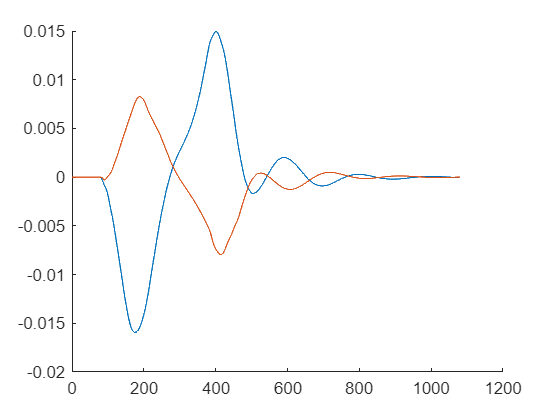

hold on
plot(steer)
plot(steer_est)
hold off